# Multilinear Singular Value Decomposition exercise

## 1. Introduction

### 1.1 Goals 

The goal of this exercise is to get familiar with multilinear singular value decomposition (MLSVD) in practice by implementing and applying it on example syntetic data. 

### 1.2 Instructions 

Your tasks will be to:

- Fill out missing pieces of code in this file,

- Complete the functions inside the 'utils' folder,

- Answer the open-ended questions in this file.

#### Files needed for this exercise

- `assignment_2_exercise_2.mlx         - `MATLAB live script that steps you through the MLSVD exercise 

- `data/example_3d_data.mat            - `Synthetic data of a 3rd order tensor 

- `data/example_4d_data.mat            - `Synthetic data of a 4th order tensor (*bonus question*)

- `*utils/mlsvd_3d.m                   - `Function that computes MLSVD for 3-D tensors

- `*utils/rec_mlsvd_3d.m               - `Function that reconstructs the original 3-D tensor from its truncted MLSVD form

- `*utils/mlsvd_Nd.m                   - `Function that computes MLSVD for tensors of any order (*bonus question*)

- `given/hidden_publish_results.p      - `Hidden function that will publish your filled in `*.m` files and `*.mlx` file into a single `.pdf` file

- `given/custom_colormap.m             - `Function to create a colormap which will ease interpretation of the data

- `given/hidden_mode_n_product.p       - `Hidden function that calculates the n-mode product between a tensor and a matrix

- `given/hidden_mode_n_matricization.p - `Hidden function that performs the unfolding of a tensor of any order in any mode 

- `given/hidden_check_mlsvd.p          - `Hidden function that checks whether your MLSVD implementation is correct. You will use this test function twice: first for a 3-D tensor and later for the N-D case.

- `given/hidden_mlsvd_3d.p             - `Hidden function that has the correct MLSVD implementation for 3-D tensors. If you cannot implement `mlsvd_3d.m` correctly by yourself, you may use this code to run MLSVD and answer the rest of the questions, or for debugging purposes.

- `given/hidden_rec_mlsvd_3d.p         - `Hidden function that has the correct implementation for the reconstruction of a 3-D input tensor from its MLSVD representation. If you cannot implement `rec_mlsvd_3d.m` correctly by yourself, you may use this code to run MLSVD-based reconstruction and answer the rest of the questions, or for debugging purposes.

- `data/example_3d_data_mlsvd.mat      - `Synthetic data of a 3rd order tensor  

- `data/example_4d_data_mlsvd.mat      - `Synthetic data of a 4th order tensor (*bonus question*)

`*`***indicates files you will need to complete***

For implementing all of the required algorithms in this exercise, [the course book ](https://arxiv.org/pdf/1609.00893.pdf)will be your main reference (particularly Section 3.4). You may also refer to [this paper](https://epubs.siam.org/doi/epdf/10.1137/S0895479896305696).

### **1.3 How to get full points**

- Hand in the homework on time. Late submissions are not taken into account and will be awarded 0 points.

- You should only submit a `*.pdf` file and the corresponding `*.mlx` file (see Submission below).

- `*.zip`** files and **`*.m`** files are not accepted, will not be graded and will be awarded 0 points**.

- All your answers and code should be visible in the `*.pdf` and the `*.mlx` files. If code lines exceed the page margin in the `*.pdf` file, make sure you break the lines in the `*.mlx` file.

- You are allowed to use your code and results from Assignment 1. 

- Make sure the output of your own functions and your plots are shown in the .pdf file.

- Write the explanation only where indicated and in text-form. Explanations given as comments in the code will not count towards the points awarded for the exercise. Nevertheless, we encourage you to follow good coding practice and use meaningful comments in the code. 

### **1.4 Submission**

- Run this `*.mlx` file including all your code and comments. 

- Uncomment and run the code block in Section 9 of this `*.mlx` file.

- Confirm that the created file "assignment_2_exercise_2_submission.pdf" includes all your code and comments in the `.mlx` file and your implementation of the `*.m` files you worked on.

- Upload the *.pdf file and this `*.mlx` file to Brightspace

- *In case the above does not work*, please copy the content of your completed .m files at the bottom of this *.mlx file and subsequently go to Live Editor -> Export -> Export to .pdf. In this case, again, upload both the *.pdf file and this *.mlx file to Brightspace.

## 2. Multilinear Singular Value Decomposition (MLSVD)

Multilinear singular value decomposition (MLSVD), also known as higher order singular value decomposition (HOSVD), is a special form of the Tucker decomposition, where all factor matrices are orthogonal and the core tensor is all-orthogonal.

In this exercise, you will implement a function which computes the MLSVD of a 3-dimensional (3D) input data tensor. 

The MLSVD form of a 3D tensor $\underline{\mathbf{T}}$ is expressed in terms of a 3D core tensor $\underline{\mathbf{C}}$, and three factor matrices in each mode (${\mathbf{U}}^{\left(1\right)} ,{\;\mathbf{U}}^{\left(2\right)}$ and ${\mathbf{U}}^{\left(3\right)}$), as shown below. 

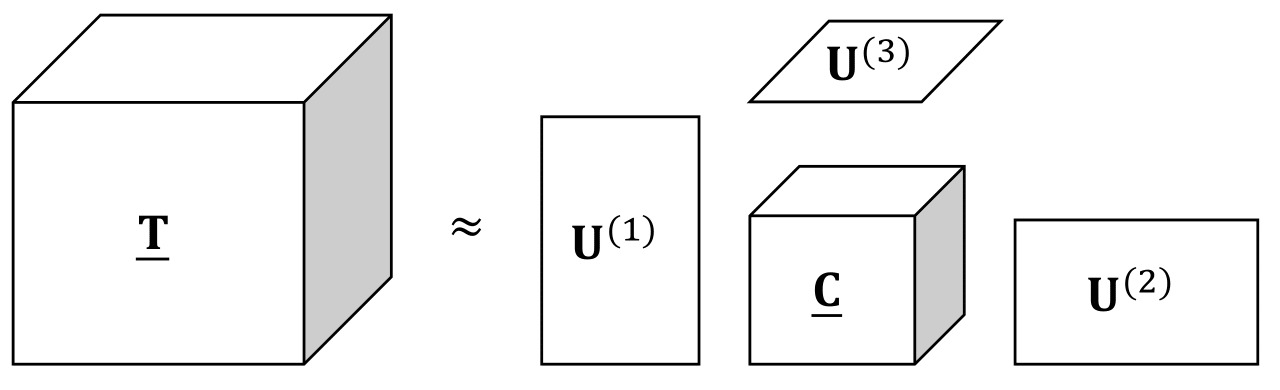

$\underline{\mathbf{T}} =\underline{\mathbf{C}} {\;\;\times }_{\;1} \;{\;\mathbf{U}}^{\left(1\right)\;} \;\times_{\;2\;} \;{\mathbf{U}}^{\left(2\right)} \;\;\times_{\;3\;} \;{\mathbf{U}}^{\left(3\right)}$.

## 3. Load synthetic data 

A synthetic data tensor of size 5x10x15 was constructed from a randomly generated core tensor and randomly generated factor matrices using a normal distribution with zero mean and unit standard deviation.

When you click the 'Run Section' button above in the Live Editor window, the helper functions included in the folders 'utils' and 'given' and the data files will be added to the search path of Matlab, and the generated tensor will be loaded as a variable T.

clear; close all; clc;
addpath(genpath('data'));
addpath(genpath('utils'));
addpath(genpath('given'));
load('example_3d_data_mlsvd.mat');

## 4. Compute MLSVD

The code `mlsvd_3d.m` has missing parts, please fill them.

[C,U1,U2,U3] = mlsvd_3d(T);

Run the test below (which internally calls your updated function `mlsvd_3d.m`) to see if your MLSVD implementation works correctly.

hidden_check_mlsvd(T);

`! `If you can not implement` mlsvd_3d.m `correctly, you may instead uncomment and run the following so that you can answer the rest of the questions in the exercise:

% [C,U1,U2,U3] = hidden_mlsvd_3d(T);

## 5. Find the multilinear rank

Inspect the values of the output core tensor by visualizing its frontal slices as a colormap:

fig = figure;
cmap = custom_colormap(); % Custom colormap to have white color centralized
for i3=1:size(T,3)
    subplot(5,3,i3);
    imagesc(C(:,:,i3),[-1 1]); colormap(cmap); colorbar; 
    title(['slice' num2str(i3)])
end
fig.Visible = 'on';

**Question**

Are there many non-zero values? What does this mean regarding the multilinear rank of the tensor?

*Your answer goes here...*

Now we will inspect the multilinear singular values of the tensor. Find and display the mode-1, mode-2 and mode-3 singular values.

**Hint 1: **Recall that the n-mode multilinear singular values are equal to the singular values of the n-mode unfolding of the tensor. 

**Hint 2: **You can use log scale in your plot(s) to better visualize the differences between the singular values, i.e., try the following:  `set(gca,'YScale','log')`

*Your code goes here...*

% Code for displaying the singular values in each mode



Write a code that outputs how many non-zero singular values exist in each mode.

*Note: You can assume that the singular values smaller than* `10^-10` *are zero. If you want to learn more about such floating point accuracy errors in finite arithmetic computations, you are welcome to check the following resources: *[*a)*](https://docs.oracle.com/cd/E19957-01/806-3568/ncg_goldberg.html)* & *[*b)*](https://papers.ssrn.com/sol3/papers.cfm?abstract_id=259379)*.*

*Your code goes here...*

% Code for determining the number of non-zero singular values in each mode

tol = 1e-10;

% n_s1 = ...
% n_s2 = ...
% n_s3 = ...

fprintf(['Number of non-zero singular values in the 1st, 2nd and 3rd mode is respectively ' ...
    '%d, %d and %d'],n_s1,n_s2,n_s3);

Determine the multilinear rank of the tensor by adjusting the sliders below.

rank_mode1 =0;
rank_mode2 =0;
rank_mode3 =0;
ml_rank = [rank_mode1,rank_mode2,rank_mode3]; % multilinear rank

disp('The multilinear rank is: ')
disp(ml_rank)

## 6. Reconstruct the original tensor from the truncated MLSVD respresentation

Using the ranks that you found in the previous step, we will create the truncated MLSVD representation of this tensor, and reconstruct the full-size tensor T_rec.

Compute the truncated representations of the factor matrices and the core tensor based on the multilinear rank.

*Your code goes here...*

% Code for truncating the MLSVD factor matrices and core tensor

% U1t = ...
% U2t = ...
% U3t = ...
% Ct = ...

Now you can reconstruct the original tensor T from its truncated MLSVD representation by filling in the missing parts of `rec_mlsvd_3d.m`.

T_rec = rec_mlsvd_3d(Ct,U1t,U2t,U3t);

Verify that the difference between the reconstructed tensor and the original tensor is insignificant via the Frobenius norm of the difference tensor, i.e. calculate $||\mathrm{T}-{\mathrm{T}}_{\textrm{rec}} ||_{\mathrm{F}}$ where $\| \cdot\|_F$ denotes the Frobenius norm.

*Your code goes here...*

% Code for computing the reconstruction error of MLSVD

% reconstructionError = ...

disp('The Frobenius norm of the difference between the original and reconstructed tensor is: ')
disp(num2str(reconstructionError));

if reconstructionError > 1e-10
    disp('The difference is too high. Please check your MLSVD reconstruction and the specified ranks.')
end

`! `If you can not implement` rec_mlsvd_3d.m `correctly (i.e., achieve a Frobenius norm less than the above threshold), you may instead uncomment and run the following so that you can answer the rest of the questions in the exercise:

% T_rec = hidden_rec_mlsvd_3d(Ct,U1t,U2t,U3t);

`! `If even with` hidden_rec_mlsvd_3d.m `you can not achieve a Frobenius norm less than the above threshold, please check again your selected ranks and your truncation of the MLSVD elements (i.e., core tensor and factor matrices).

### 6.1 Find the compression ratio

Let's copmpute how much we could compress the input tensor by comparing the number of elements in the original tensor with the number of elements needed in the truncated MLSVD form. Fill in the blank parts of the code below. 

*Your code goes here...*

% Code for finding the compression ratio

% num_el_original = ...
% num_el_truncated = ...

disp('The achieved compression ratio is: ')
disp(num2str(num_el_truncated/num_el_original));

## 7. Noisy case

Real-life measurements are often noisy, and it is a challenging problem to determine the rank of the data in the presence of noise. Note that, this is an inherent challenge not only for tensors, but for the matrix case as well. 

Generate a Gaussian noise tensor of same size as T with unit variance and 0 mean.

*Your code goes here...*

% Code for generating noise

% noise = ...

Let us add the noise to the original tensor:

noise = noise./norm(noise(:),'fro').*norm(T(:),'fro'); 
SNR = 10; 
T_noisy = T + noise*(1/SNR); % After we ensure that the noise term and the input tensor originally have the same norm 
% (two lines above), we can then adjust the power of the added noise to obtain the desired signal-to-noise ratio (SNR).

### 7.1 Multilinear rank of the noisy tensor

In this subtask we will observe the effect of noise on the multilinear rank of the data. 

Inspect the singular values of the noisy tensor, and compare them to the singular values of the original tensor by visualizing them on the same plot (you can do this for any selected mode).

*Your code goes here...*

% Code for comparing the singular values with and without noise



**Question**

What do you observe? Are there still singular values that are zero? What happens if you decrease the SNR? Can you still determine which singular values belong to the signal and which belong to noise?

*Your answer goes here...*

**Question**

If you were to determine the multilinear rank of some noisy real-life measurements, what kind of approach would you follow?

*Your answer goes here...*

### 7.2 MLSVD of the noisy tensor

By assuming the **same** multilinear ranks found in the noisefree case, try to recunstruct back a tensor (T_rec_n) from the MLSVD of its noise-added version. 

[C_n,U1_n,U2_n,U3_n] = mlsvd_3d(T_noisy);

*Your code goes here...*

% U1_n_t = ...
% U2_n_t = ...
% U3_n_t = ...
% C_n_t = ...


T_rec_n = rec_mlsvd_3d(C_n_t,U1_n_t,U2_n_t,U3_n_t);

% NOTE: If you couldn't implement rec_mlsvd_3d.m correctly, you may uncomment and run the line below instead:
% T_rec_n = hidden_rec_mlsvd_3d(C_n_t,U1_n_t,U2_n_t,U3_n_t);


disp('The Frobenius norm of the difference between the original (i.e., noisy) and reconstructed tensor is: ')
% % Your code goes here...

disp('The Frobenius norm of the difference between the noiseless and reconstructed tensor is: ')
% % Your code goes here...


**Question**

Is the reconstructed tensor closer to the noiseless or noisy tensor? What do you think is the reason for your observation? Does your observation change with respect to the noise level?

*Your answer goes here...*

## 8. Bonus - MLSVD for higher order tensors

Can you implement MLSVD for higher order ( > 3) tensors? Please fill in the missing parts of  `mlsvd_Nd.m`.

% Load the data
load('example_4d_data_mlsvd');

[C_Xd,U_Xd] = mlsvd_Nd(T_Xd);

Run the code below to test if your MLSVD implementation works correctly.

hidden_check_mlsvd(T_Xd);

Determine the rank of this tensor.

*Your code goes here...*

% Code for determining the multilinear rank



Adjust the sliders below to the rank that you found.

rank_mode1 =0;
rank_mode2 =0;
rank_mode3 =0;
rank_mode4 =0;

fprintf('The multilinear rank of the 4D tensor is %d, %d, %d and %d',rank_mode1,rank_mode2,rank_mode3,rank_mode4);

## 9. Prepare results for submission

Uncomment the following code lines and run the code to prepare the .pdf file for submission. (Running this code block might take a while.)

% hidden_publish_results('assignment_2_exercise_2_submission.pdf', ...
% 'assignment_2_exercise_2.mlx', 'utils', {'mlsvd_3d.m', 'rec_mlsvd_3d.m', 'mlsvd_Nd.m'})